% Effect of Network Topology on the Performance of ADMM-Based SVMs

clear; clc; close all;
addpath(genpath('code'));
warning('off', 'all');   

projectRoot = fileparts(mfilename('fullpath'));
dataDir    = fullfile(projectRoot, 'data');
resultsDir = fullfile(projectRoot, 'results');
plotsDir   = fullfile(projectRoot, 'plots');
if ~exist(resultsDir, 'dir'), mkdir(resultsDir); end
if ~exist(plotsDir, 'dir'), mkdir(plotsDir); end

% === ADMM Parameters ===
maxIters = 300;                   % more iterations so ADMM has time to converge
cvFolds  = 3;                     
shuffles = 5;                    
% Relative + absolute tolerances (Boyd et al.)
ABSTOL   = 1e-3;
RELTOL   = 1e-3;
tol_pri  = ABSTOL; 
tol_dual = RELTOL;    % ADMM dual tolerance

% Graph groups and datasets
% - Two graph groups: G1 (n=16, d ∈ {3,5,7,9,11,13,15}) for small datasets;
%   G2 (n=128, d ∈ {10,20,30,40,50,60,70,80,90,100}) for large datasets.
G1.n = 16;            G1.degrees = [3,5,7,9,11,13,15];
G2.n = 128;           G2.degrees = [10,20,30,40,60,70,80,90];

datasets_small = {'ionosphere','svmguid'};
datasets_large = {'phishing','a9a','skinNonskin','ijcnn'};

% Hyperparameter grids (rho, J*C, gamma (RBF))
rho_grid   = 0.01;
JC_grid    = 0.1;      % JC = J*C (J = #nodes)
gamma_grid = 1e-3;

%% RFF options (disabled by default)
useRFF  = false;   % keep false unless you have RFF-enabled consensus_admm_svm
rffDim  = 0;       % 0 means "do not use RFF" (no extra args passed)
rffSeed = 42;      % dummy seed (only used if useRFF=true and rffDim>0)


%% Download/load datasets (LIBSVM/UCI)
% Data utils will cache to ./data once downloaded.
dsSmall = cellfun(@(n) load_dataset(n, dataDir), datasets_small, 'UniformOutput', false);

Loaded dataset: ionosphere
  Train size: 300, Test size: 51
  Features: 34
  Labels after normalization: [-1;1]

Loaded dataset: svmguid
  Train size: 3089, Test size: 4000
  Features: 4
  Labels after normalization: [-1;1]



dsLarge = cellfun(@(n) load_dataset(n, dataDir), datasets_large, 'UniformOutput', false);

Loaded dataset: phishing
  Train size: 5000, Test size: 5000
  Features: 68
  Labels after normalization: [-1;1]

Loaded dataset: a9a
  Train size: 32561, Test size: 16281
  Features: 123
  Labels after normalization: [-1;1]

Loaded dataset: skinNonskin
  Train size: 37492, Test size: 5000
  Features: 3
  Labels after normalization: [-1;1]

Decompressing C:\Users\chara\AppData\Local\Temp\Editor_sqylw\data\ijcnn1.tr.bz2 with 7-Zip...
Decompressing C:\Users\chara\AppData\Local\Temp\Editor_sqylw\data\ijcnn1.t.bz2 with 7-Zip...
Loaded dataset: ijcnn
  Train size: 35000, Test size: 91701
  Features: 22
  Labels after normalization: [-1;1]



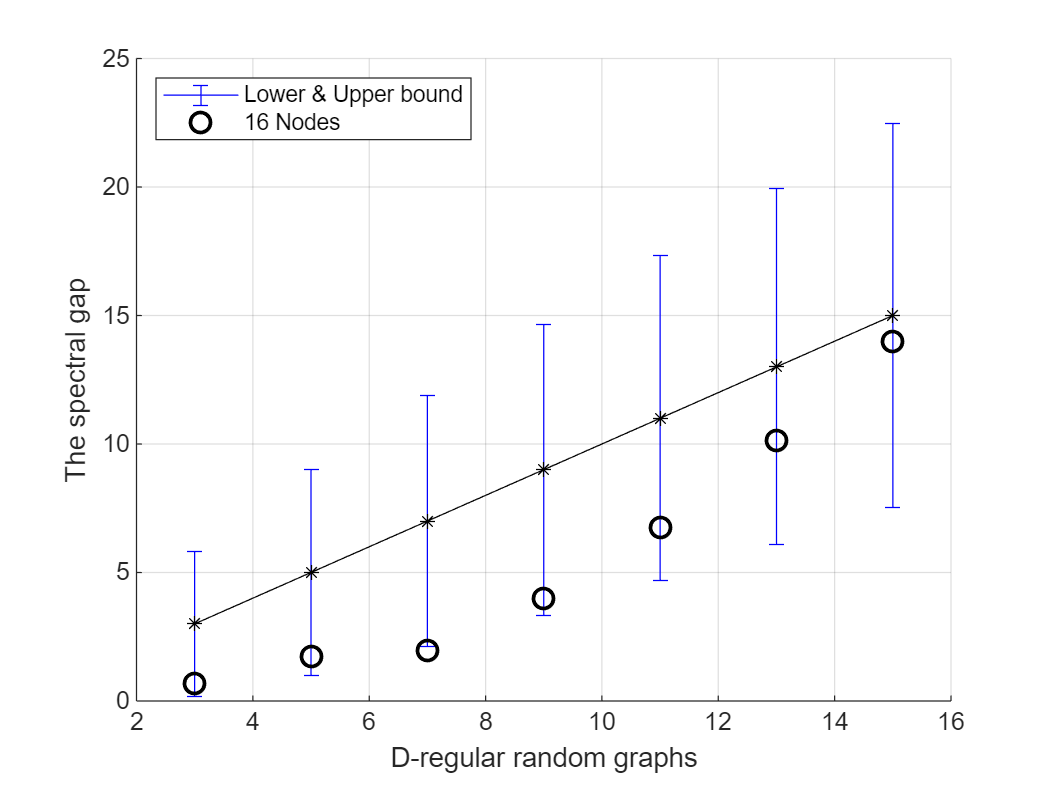


%% Helper: run experiment for a dataset set and graph group
function S = run_experiments_for_group(dsCell, groupName, Nnodes, degreeList, maxIters, cvFolds, shuffles, ...
                                       rho_grid, JC_grid, gamma_grid, tol_pri, tol_dual, resultsDir, plotsDir)

    % Pre-allocate summary
    S = struct();
    S.group     = groupName;
    S.Nnodes    = Nnodes;
    S.degrees   = degreeList;
    S.datasets  = cellfun(@(d) d.name, dsCell, 'UniformOutput', false);
    S.results   = containers.Map(); % key: dataset name, value: table

    for dsi = 1:numel(dsCell)
        D = dsCell{dsi};
        fprintf('\n\n======================\n   DATASET: %s\n======================\n\n', D.name);

        degs = degreeList;
        perDeg = table('Size', [numel(degs) 8], 'VariableTypes', ...
            {'double','double','double','double','double','double','double','double'}, ...
            'VariableNames', {'degree','lambda2','lambda2_lb','lambda2_ub','iters_mean','time_mean','acc_mean','converged_rate'});

        for k = 1:numel(degs)
            d = degs(k);
            fprintf('   -> Generating %d-regular graph with N=%d\n', d, Nnodes);
            % Using MATLAB built-in generator
try
    G = randreg(Nnodes, d);   % built-in random d-regular graph
    A = adjacency(G);
catch
    % Fallback: custom generator
    A = random_d_regular_graph(Nnodes, d);
end
           % adjacency
            L = laplacian(A);
            lambda = sort(eig(L));
            lambda2 = lambda(2);                              % spectral gap (λ2)

            % Bounds per (11)/(12): Ramanujan lower/upper (ε≈0)
            [lb, ub] = ramanujan_bounds_lambda2(d);          % Joel Friedman/Morgenstern bounds

            % Store star in plots later if Ramanujan-ish
            isR = is_ramanujan(A);

            % Consensus ADMM-SVM over shuffles; record mean time/iters/acc
            iters = zeros(shuffles,1);
            times = zeros(shuffles,1);
            accs  = zeros(shuffles,1);
            convd = zeros(shuffles,1);

            for s = 1:shuffles
    [Xtr, ytr, Xte, yte] = shuffled_split(D);

    % --- NEW: force labels to {-1,+1} consistently for both train and test
    [ytr_pm1, yte_pm1] = make_labels_pm1(ytr, yte);

    % normalize/standardize if needed
    [XtrN, XteN] = normalize_if_needed(Xtr, Xte);

    % choose hyperparams by CV (rho, JC, gamma) for consensus ADMM-SVM
    [rho_best, JC_best, gamma_best] = gridsearch_cv_admm_svm( ...
        XtrN, ytr_pm1, Nnodes, rho_grid, JC_grid, gamma_grid, ...
        cvFolds, tol_pri, tol_dual, maxIters);

    % run training distributed over graph (shared-memory simulated workers)
    tic;
    [model, info] = consensus_admm_svm(XtrN, ytr, A, rho_best, JC_best/Nnodes, gamma_best, maxIters, tol_pri, tol_dual);
    elapsed = toc;   % record training time


    % Predict: predictor returns raw decision scores f(x)
    scores = predict_svm_rbf(model, XteN);

    % Evaluate in the same label space {-1,+1}
    acc  = mean(sign(scores) == yte_pm1);

                iters(s) = info.iters;
                times(s) = elapsed;
                accs(s)  = acc;
                convd(s) = info.converged;
            end

            perDeg.degree(k)        = d;
            perDeg.lambda2(k)       = lambda2;
            perDeg.lambda2_lb(k)    = lb;
            perDeg.lambda2_ub(k)    = ub;
            perDeg.iters_mean(k)    = mean(iters);
            perDeg.time_mean(k)     = mean(times);
            perDeg.acc_mean(k)      = mean(accs);
            perDeg.converged_rate(k)= mean(convd);
        end

        % Save CSV
        outCsv = fullfile(resultsDir, sprintf('%s_%s_summary.csv', groupName, D.name));
        writetable(perDeg, outCsv);
        S.results(D.name) = perDeg;

        % Plots analogous to paper
        plot_spectral_gap_bounds(perDeg, groupName, D.name, plotsDir);
        plot_iters_time(perDeg, groupName, D.name, plotsDir);
    end
end

%% === Spectral Gap Experiments===
% Dependent only on graph topology, not on datasets.

% --- Case 1: Small graphs (N=16, d = 3:2:15) ---
N = G1.n; degs = G1.degrees;
lambda2_vals = zeros(size(degs));
lambda2_lb   = zeros(size(degs));
lambda2_ub   = zeros(size(degs));

for i=1:numel(degs)
    d = degs(i);
    try
        G = randreg(N, d);
        A = adjacency(G);
    catch
        A = random_d_regular_graph(N, d);
    end
    L = laplacian(A);
    eigvals = sort(eig(L));
    lambda2_vals(i) = eigvals(2); % spectral gap
    [lb, ub] = ramanujan_bounds_lambda2(d);
    lambda2_lb(i) = lb;
    lambda2_ub(i) = ub;
end

figure; hold on;
errorbar(degs, (lambda2_lb+lambda2_ub)/2, ...
         (lambda2_ub-lambda2_lb)/2, 'b');
plot(degs, lambda2_vals, 'ko', 'MarkerSize', 8, 'LineWidth', 1.5);
plot(degs, (lambda2_lb+lambda2_ub)/2, 'k-*');
xlabel('D-regular random graphs'); ylabel('The spectral gap');
legend('Lower & Upper bound','16 Nodes','Location','NorthWest');
grid on;
saveas(gcf, fullfile(plotsDir,'Fig1_spectral_gap_N16.png'));

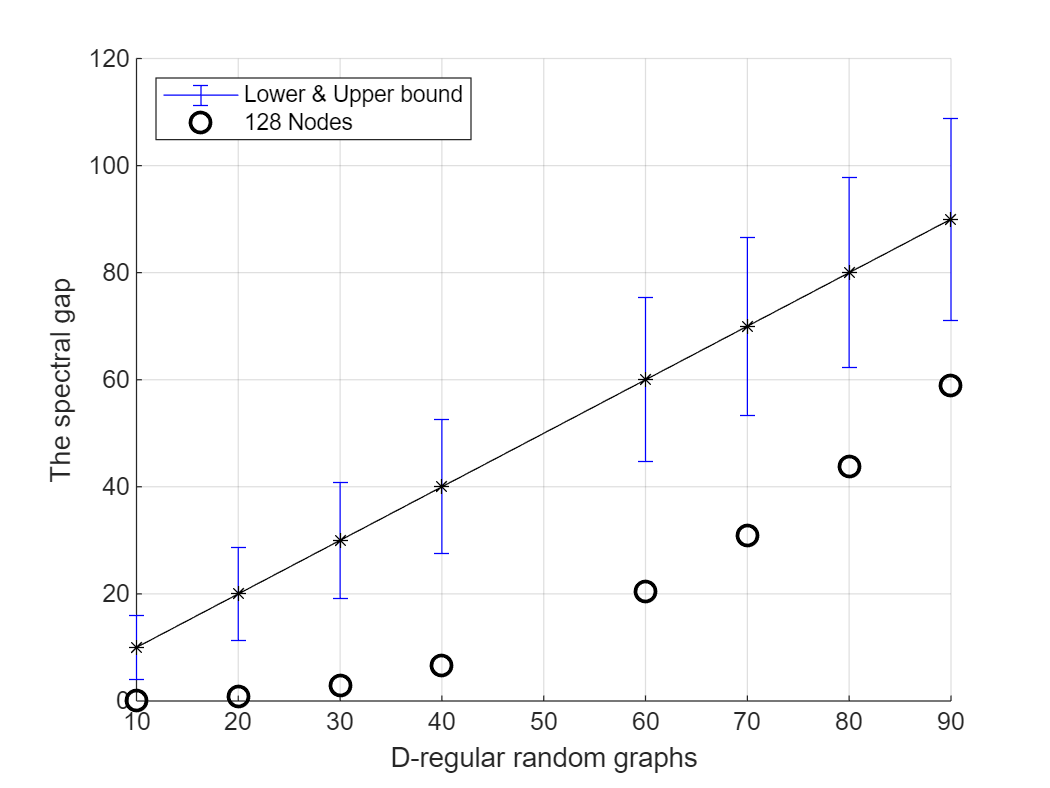


% --- Case 2: Large graphs (N=128, d = 10:10:100) ---
N = G2.n; degs = G2.degrees;
lambda2_vals = zeros(size(degs));
lambda2_lb   = zeros(size(degs));
lambda2_ub   = zeros(size(degs));

for i=1:numel(degs)
    d = degs(i);
    try
        G = randreg(N, d);
        A = adjacency(G);
    catch
        A = random_d_regular_graph(N, d);
    end
    L = laplacian(A);
    eigvals = sort(eig(L));
    lambda2_vals(i) = eigvals(2);
    [lb, ub] = ramanujan_bounds_lambda2(d);
    lambda2_lb(i) = lb;
    lambda2_ub(i) = ub;
end

figure; hold on;
errorbar(degs, (lambda2_lb+lambda2_ub)/2, ...
         (lambda2_ub-lambda2_lb)/2, 'b');
plot(degs, lambda2_vals, 'ko', 'MarkerSize', 8, 'LineWidth', 1.5);
plot(degs, (lambda2_lb+lambda2_ub)/2, 'k-*');
xlabel('D-regular random graphs'); ylabel('The spectral gap');
legend('Lower & Upper bound','128 Nodes','Location','NorthWest');
grid on;
saveas(gcf, fullfile(plotsDir,'Fig2_spectral_gap_N128.png'));



%% Run G1 on small datasets
S1 = run_experiments_for_group(dsSmall, 'G1', G1.n, G1.degrees, maxIters, cvFolds, shuffles, ...
                               rho_grid, JC_grid, gamma_grid, tol_pri, tol_dual, resultsDir, plotsDir);



   DATASET: ionosphere

   -> Generating 3-regular graph with N=16
   -> Generating 5-regular graph with N=16
   -> Generating 7-regular graph with N=16
   -> Generating 9-regular graph with N=16
   -> Generating 11-regular graph with N=16
   -> Generating 13-regular graph with N=16
   -> Generating 15-regular graph with N=16


   DATASET: svmguid

   -> Generating 3-regular graph with N=16
   -> Generating 5-regular graph with N=16
   -> Generating 7-regular graph with N=16
   -> Generating 9-regular graph with N=16
   -> Generating 11-regular graph with N=16
   -> Generating 13-regular graph with N=16
   -> Generating 15-regular graph with N=16



%% Run G2 on large datasets
S2 = run_experiments_for_group(dsLarge, 'G2', G2.n, G2.degrees, maxIters, cvFolds, shuffles, ...
                               rho_grid, JC_grid, gamma_grid, tol_pri, tol_dual, resultsDir, plotsDir);



   DATASET: phishing

   -> Generating 10-regular graph with N=128
   -> Generating 20-regular graph with N=128
   -> Generating 30-regular graph with N=128
   -> Generating 40-regular graph with N=128
   -> Generating 60-regular graph with N=128
   -> Generating 70-regular graph with N=128
   -> Generating 80-regular graph with N=128
   -> Generating 90-regular graph with N=128


   DATASET: a9a

   -> Generating 10-regular graph with N=128
   -> Generating 20-regular graph with N=128
   -> Generating 30-regular graph with N=128
   -> Generating 40-regular graph with N=128
   -> Generating 60-regular graph with N=128
   -> Generating 70-regular graph with N=128
   -> Generating 80-regular graph with N=128
   -> Generating 90-regular graph with N=128


   DATASET: skinNonskin

   -> Generating 10-regular graph with N=128
   -> Generating 20-regular

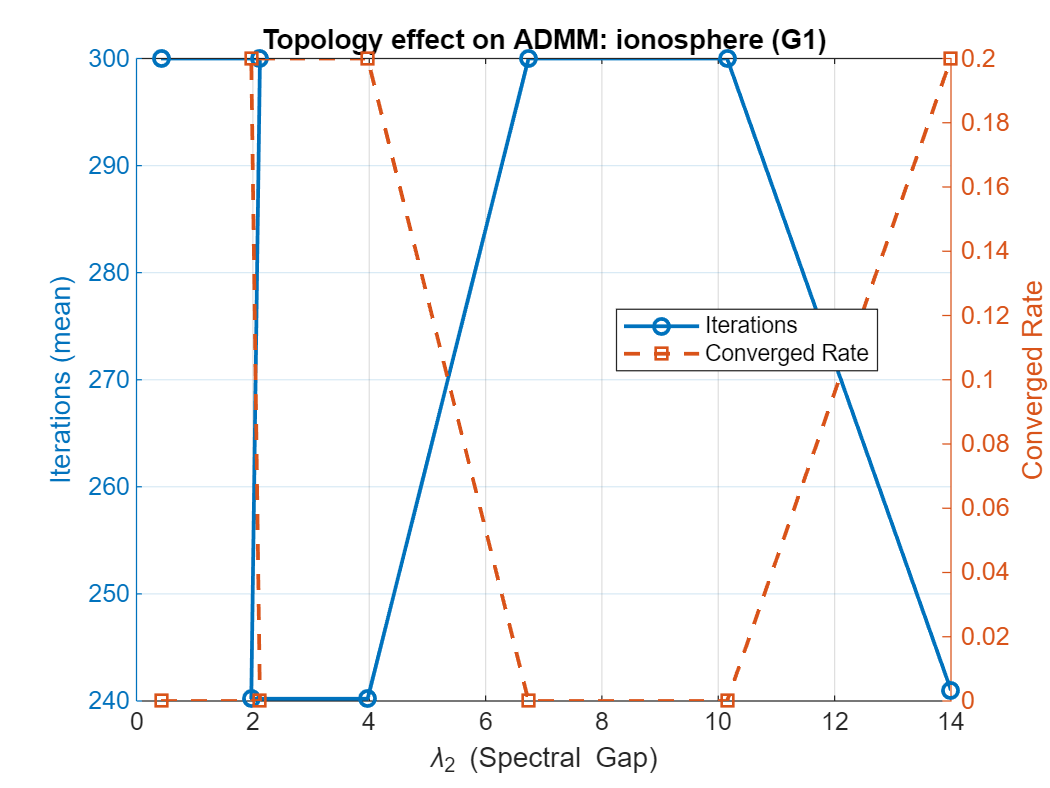

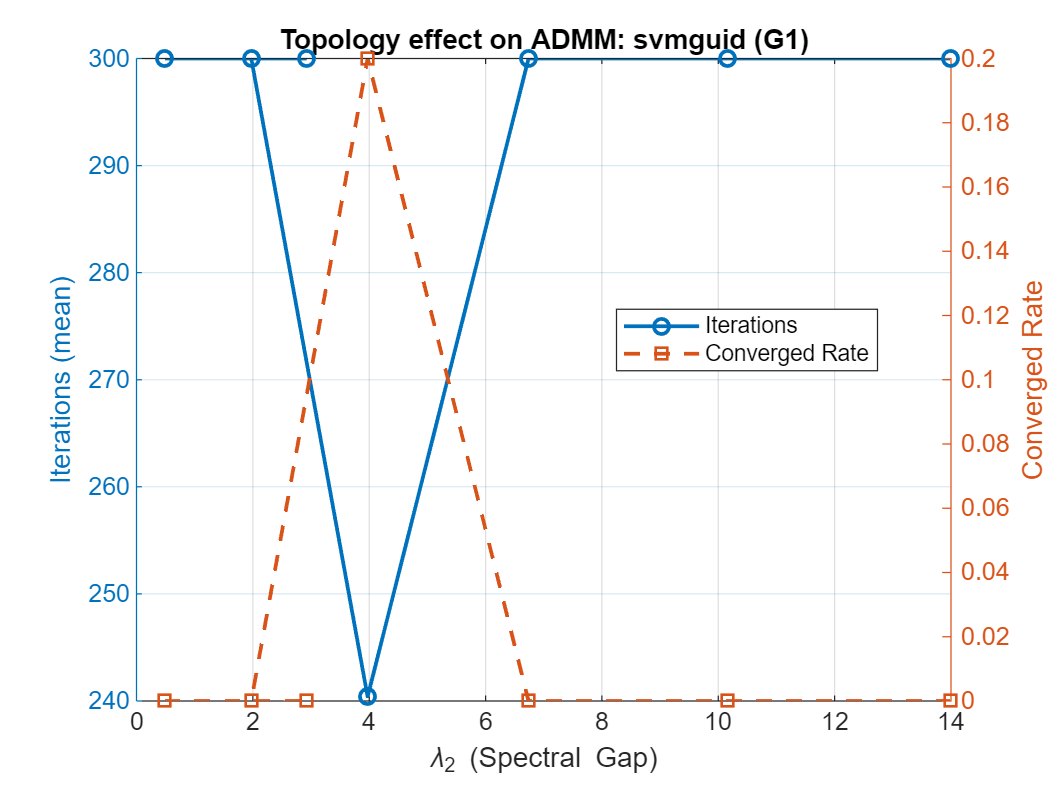


%% --- Topology effect plots for each dataset ---
for i = 1:numel(S1.datasets)
    dname = S1.datasets{i};
    perDeg = S1.results(dname);
    plot_topology_effect(perDeg, dname, 'G1', plotsDir);
end

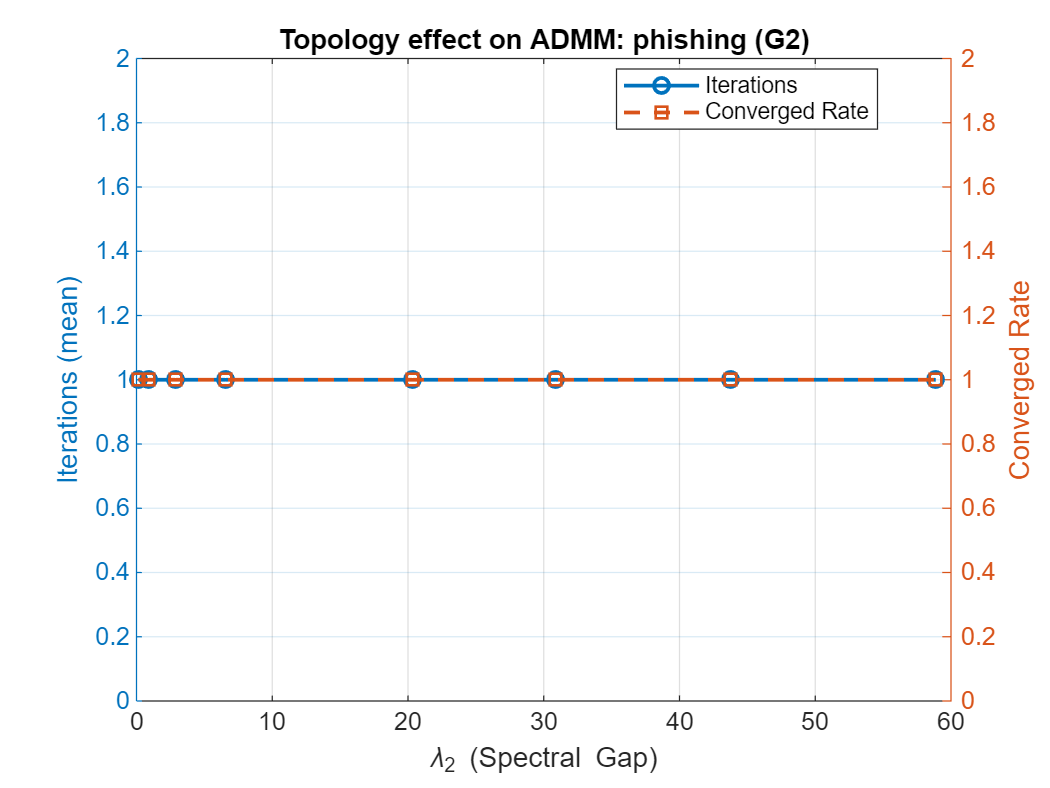

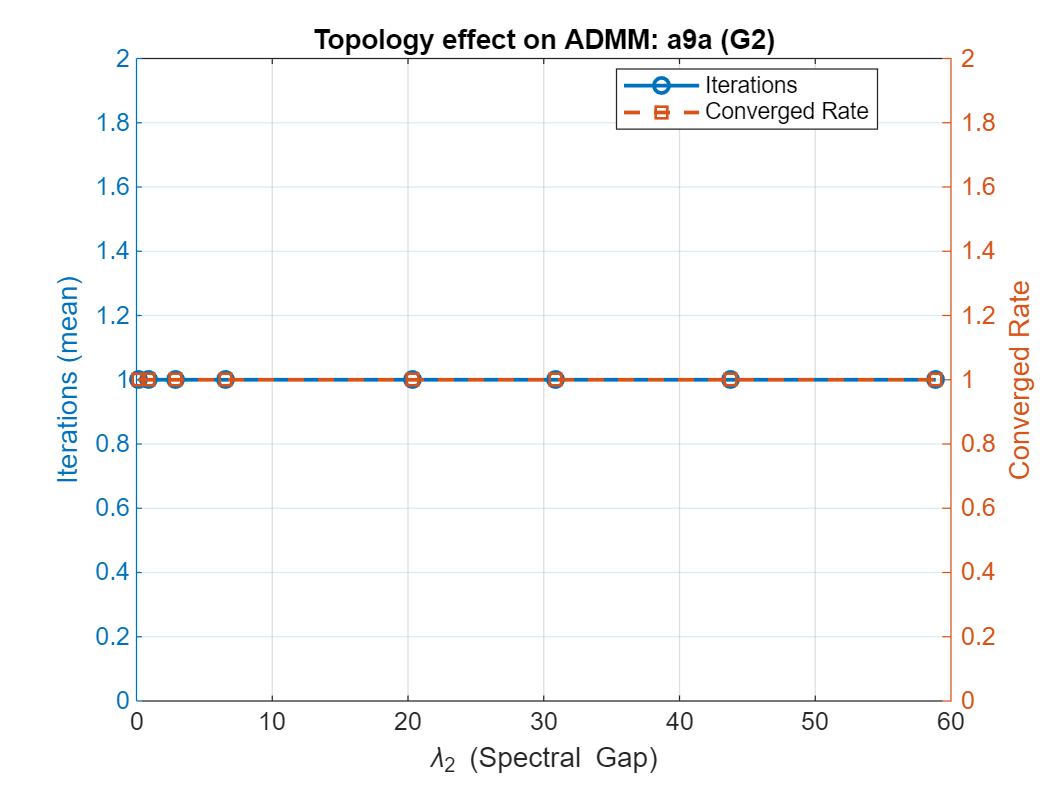

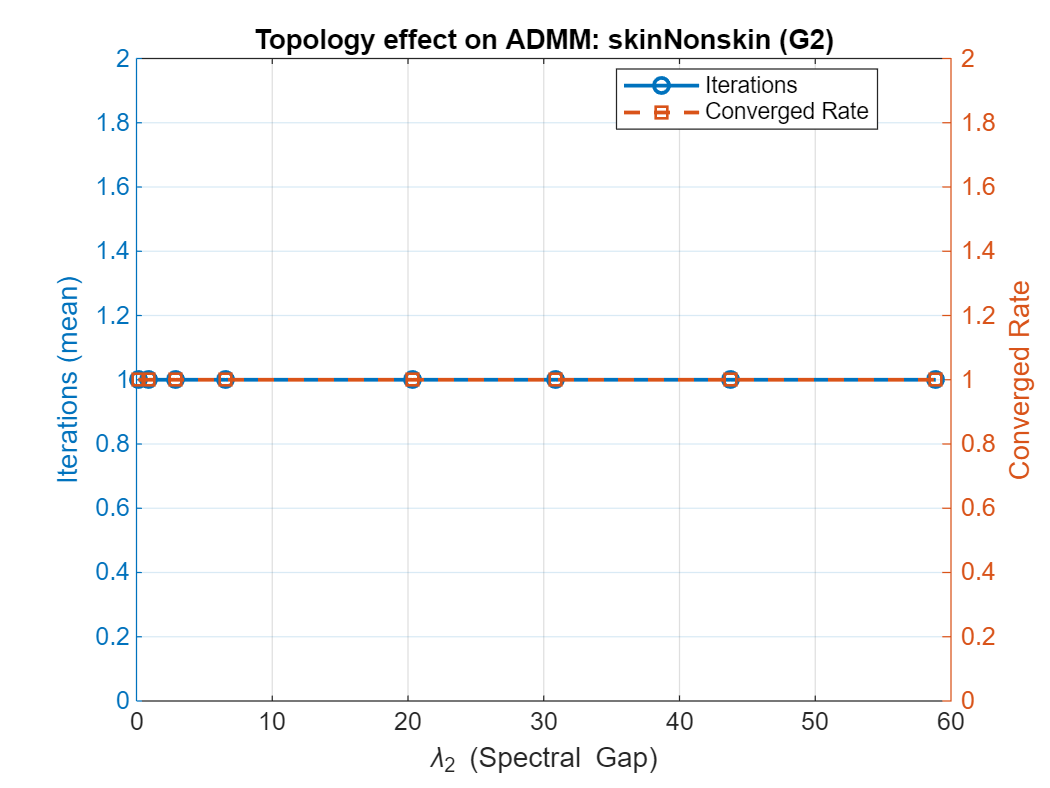

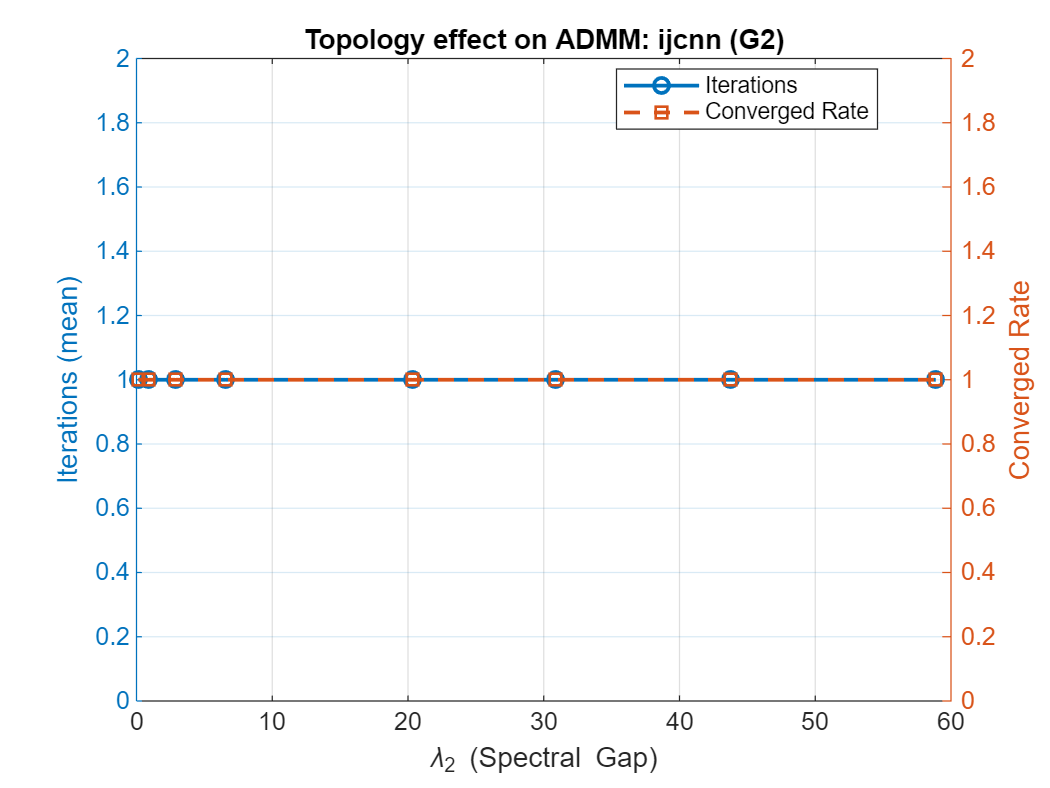


for i = 1:numel(S2.datasets)
    dname = S2.datasets{i};
    perDeg = S2.results(dname);
    plot_topology_effect(perDeg, dname, 'G2', plotsDir);
end



% 16-node group (svmguid + ionosphere)
plot_iters_time_group(S1, plotsDir, 'Fig3_G1_iters_time');

% 128-node group (phishing, a9a, skinNonskin, ijcnn)
plot_iters_time_group(S2, plotsDir, 'Fig4_G2_iters_time');


%% Aggregate & reproduce combined plots
% plots are saved per-dataset

disp('All experiments completed. See ./results and ./plots.');

All experiments completed. See ./results and ./plots.
